# Find Peaks in Signals

Instructions are in the task pane to the left. Complete and submit each task one at a time. Do not edit. This code loads and plots the data.

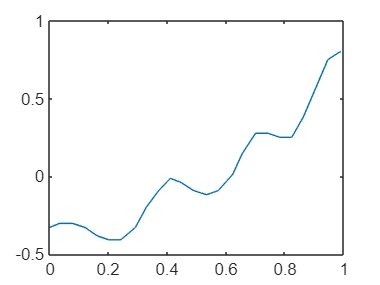

load sampleletters.mat
plot(m1.Time,m1.X)

## Task 1

Local minima and maxima are often important features of a signal. The `islocalmin` and `islocalmax` functions take a signal as input and return a logical array the same length as the signal.

`idx` `=` `islocalmin``(``x``)``;`

The value of `idx` is `true` whenever the corresponding value in the signal is a local minimum.

**TASK**

Use the `islocalmin` and `islocalmax` functions to create two logical arrays, `idxmin` and `idxmax`, respectively, that determine the local minima and maxima of `m1.X`.

**Hint**

Pass `m1.X` as an input to both the `islocalmin` and `islocalmax` functions.

idxmin=islocalmin(m1.X)

idxmin = 27×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0


idxmax=islocalmax(m1.X)

idxmax = 27×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


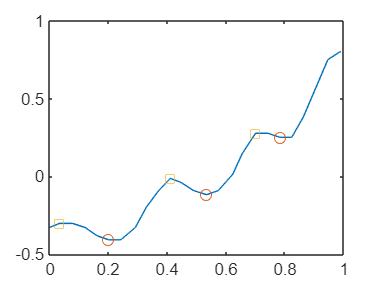

% Visualize the results
plot(m1.Time,m1.X)
hold on
plot(m1.Time(idxmin),m1.X(idxmin),"o")
plot(m1.Time(idxmax),m1.X(idxmax),"s")
hold off

## Task 2

Local minima and maxima are defined by computing the *prominence* of each value in the signal. The prominence is a measure of how a value compares to the other values around it. You can obtain the prominence value of each point in a signal by obtaining a second output from `islocalmin` or `islocalmax`.

`[``idx``,``p``]` `=` `islocalmin``(``x``)``;`

**TASK**

Determine the prominence values for `islocalmin``(``m1.X``)`. Store the result in a variable called `prom`. Plot the prominence as a function of the `Time` variable of `m1`.

**Hint**

Use two outputs for `islocalmin``(``m1.X``)` to obtain `prom` (the second output). Pass `m1.Time` and `prom` as inputs to the `plot` function.

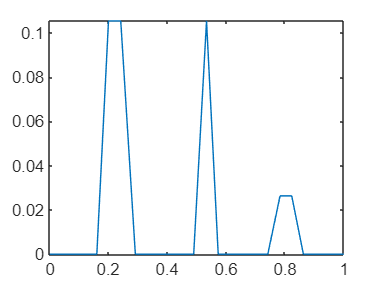

[idx,prom] = islocalmin(m1.X);
plot(m1.Time,prom)

## Task 3

By default, `islocalmin` and `islocalmax` find points with any prominence value above 0. This means that a maximum is defined as any point that is larger than the two values on either side of it. For noisy signals you might want to consider only minima and maxima that have a prominence value above a given threshold.

`idx` `=` `islocalmin``(``x``,``"MinProminence"``,``threshvalue``)`

When choosing a threshold value, note that prominence values can range from 0 to `range``(``x``)`.

**TASK**

Recalculate `idxmin` and `idxmax` for `m1.X` using a minimum prominence threshold of `0.1`. Copy the plotting code from task 1 to visualize the result.

**Hint**

Repeat the commands from task 1, adding the `"MinProminence"` option.

idxmin = islocalmin(m1.X,"MinProminence",0.1)

idxmin = 27×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0


idxmax = islocalmax(m1.X,"MinProminence",0.1)

idxmax = 27×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
